# EE-414 Speech Processing Lab

#  Lab-6

## Aim 

#### ● To understand the need for short term processing of speech.

#### ● To compute short term energy and study its significance. 

#### ● To compute short term zero crossing rate and study its significance. 

#### ● To compute short term autocorrelation and study its significance. 

## Introduction:

Why do we need short term processing of speech? Speech signals are inherently non-stationary in nature, which means that the properties are changing with respect to time. The methods and techniques we use for LTI systems will not give proper information when we use these same techniques for speech signals, as these are not time invariant. Hence there is a need to modify these techniques and methods so that we can use these to get valid results in the case for speech signals as well. Hence the term short term processing came into picture, which takes small intervals of the speech signal and assume these small blocks to be stationary over the specific interval of the block. So while assuming stationarity holds true in each block, we can apply the techniques in each block and get meaningful results. 

Spectrogram and Waveform of "Speech Signal" from wavesurfer

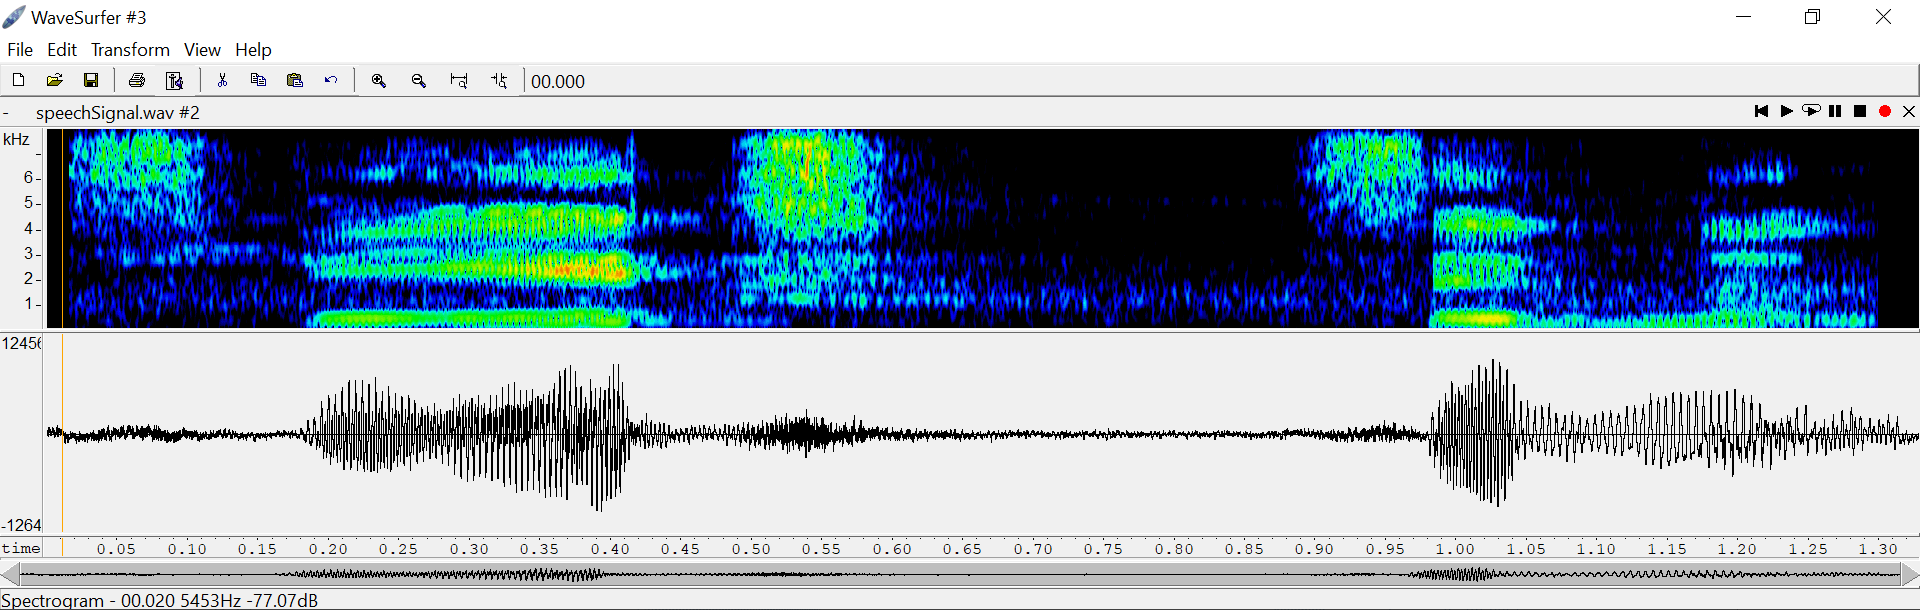

### A. Short term energy(STE) : 

a. Compute and plot STE (as a function of frame index) using frame size as 20ms and frameshift as 10ms. 

b. Demonstrate and explain the effect of the window size on STE by taking window size of 20ms, 30ms, 50ms, 100ms. Also comment on which frame size is preferred. 

#### Theory:

We know that the energy for speech signals is time varying in nature, hence we use the short term energy which involves taking energy in each block (assuming stationarity in each of these blocks).

The formula for short term energy is:

where '*w(n)'* represent the windowing function of finite duration and '*n'* is the shift / rate in number of samples at which we are interested in knowing the short term energy.

Short time energy is defined as the sum of squares of samples in one frame. By dividing speech signal into overlapping frames, we can observe these quasi-stationary frames and do a better analysis. 

#### Procedure:

We first take the original speech signal and we divide the sound segments into frames with particular frameshift and framesize, and calculate the energy in each of these frames (which is done by the user defined function *calculate_energy(fs, frame_size, frame_shift, signal)*). We then plot the short time energy for each frame index and we will take different frame sizes and observe the differences.

#### **Code:**

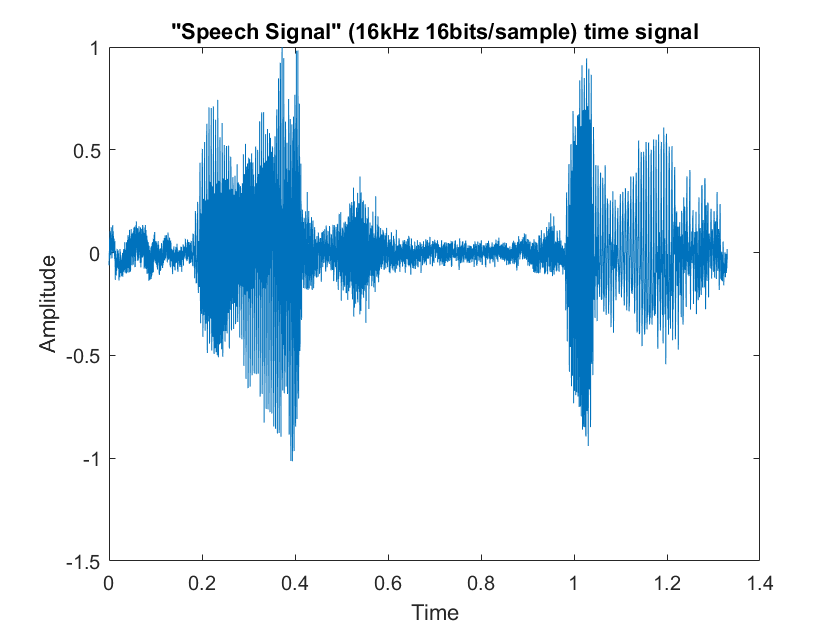

close all; clc; clear all;

[y,fs]=audioread('speechSignal.wav'); 
% sound(y, fs);

sound_sample = y(:,1); % Taking left channel
sound_sample = sound_sample./max(sound_sample); % Normalizing

% "Speech Signal" 
plot_time_signal(sound_sample, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

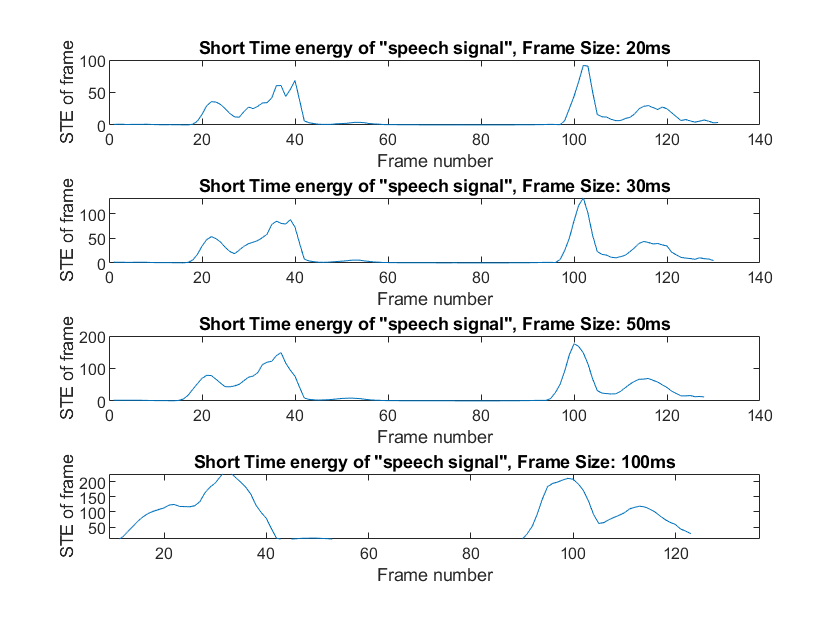

frame_shift = 0.010;

% Frame Size = 20 ms
frame_size = 0.020;
[no_of_frames, E] = calculate_energy(fs, frame_size, frame_shift, sound_sample);
subplot(411);
plotting((1:no_of_frames), E, 'Short Time energy of "speech signal", Frame Size: 20ms', 'Frame number', 'STE of frame');

% Frame Size = 30 ms
frame_size = 0.030;
[no_of_frames, E] = calculate_energy(fs, frame_size, frame_shift, sound_sample);
subplot(412);
plotting((1:no_of_frames), E, 'Short Time energy of "speech signal", Frame Size: 30ms', 'Frame number', 'STE of frame');

% Frame Size = 50 ms
frame_size = 0.050;
[no_of_frames, E] = calculate_energy(fs, frame_size, frame_shift, sound_sample);
subplot(413);
plotting((1:no_of_frames), E, 'Short Time energy of "speech signal", Frame Size: 50ms', 'Frame number', 'STE of frame');

% Frame Size = 100 ms
frame_size = 0.100;
[no_of_frames, E] = calculate_energy(fs, frame_size, frame_shift, sound_sample);
subplot(414);
plotting((1:no_of_frames), E, 'Short Time energy of "speech signal", Frame Size: 100ms', 'Frame number', 'STE of frame');

#### Observations:

As we increase the frame size, the energy curve becomes smoother. So it is more difficult to know where the voiced and unvoiced regions are (sharp distinction for these are reduced). We might miss out regions which are actually unvoiced as we increase the frame size. Normally for speech processing, frame size for STE is about 10-30 msec and here we shall choose 20 ms as frame size. Also we see high energy for voiced speech (as there is coninuous airflow without stoppage) whereas we do not see much energy for unvoiced speech.

### B. Short term Zero Crossing Rate(ST-ZCR) :

a. Compute and plot ST-ZCR for speech signal using frame size as 20ms and frameshift as 10ms. 

b. Demonstrate and explain the effect of the window on ST-ZCR by taking window size of 20ms, 30ms, 50ms, 100ms. Also comment on which frame size is preferred. 

#### Theory:

ZCR is defined as the number of times zero axis is crossed per frame. By dividing speech signal into overlapping frames, we can observe these quasi-stationary frames and do a better analysis.

ZCR for stationary signals:

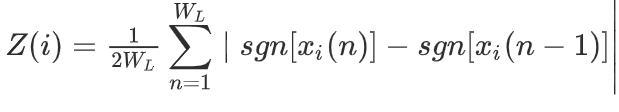 

ZCR for non-stationary signals:

If ZCR is high, it means the signal is varying rapidly, implying high frequency; whereas if ZCR is low, the signal is varying slowly and is more stable and implies low frequency components are present.

#### Procedure:

We first take the original speech signal and we divide the sound segments into frames with particular frameshift and framesize, and calculate the ZCR in each of these frames (which is done by the user defined function *calculate_zcr(fs, frame_size, frame_shift, signal)*). We then plot the ZCR for each frame index and we will take different frame sizes and observe the differences.

#### **Code:**

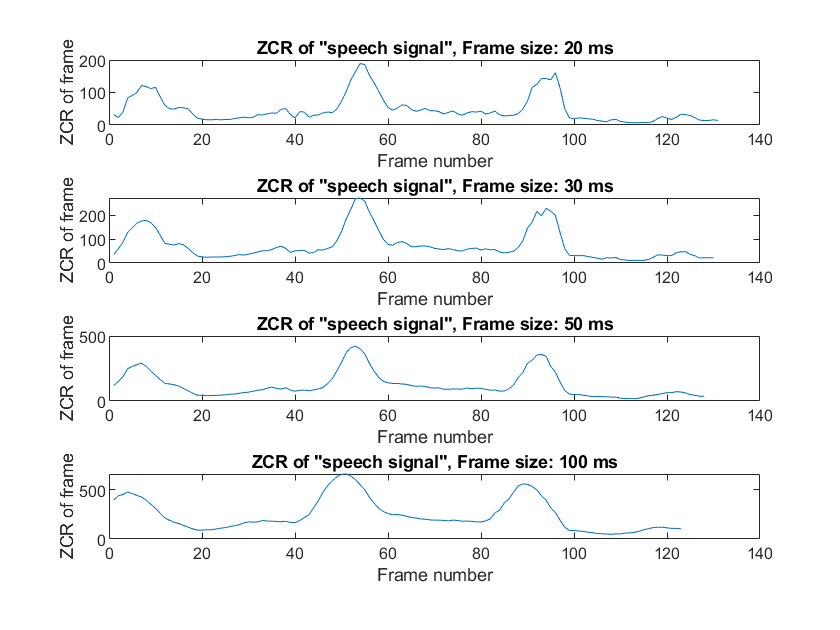

close hidden

frame_shift = 0.010;

% Frame Size = 20 ms
frame_size = 0.020;
[no_of_frames, zcr] = calculate_zcr(fs, frame_size, frame_shift, sound_sample);
subplot(411);
plotting((1:no_of_frames), zcr, 'ZCR of "speech signal", Frame size: 20 ms', 'Frame number', 'ZCR of frame');

% Frame Size = 30 ms
frame_size = 0.030;
[no_of_frames, zcr] = calculate_zcr(fs, frame_size, frame_shift, sound_sample);
subplot(412);
plotting((1:no_of_frames), zcr, 'ZCR of "speech signal", Frame size: 30 ms', 'Frame number', 'ZCR of frame');

% Frame Size = 50 ms
frame_size = 0.050;
[no_of_frames, zcr] = calculate_zcr(fs, frame_size, frame_shift, sound_sample);
subplot(413);
plotting((1:no_of_frames), zcr, 'ZCR of "speech signal", Frame size: 50 ms', 'Frame number', 'ZCR of frame');

% Frame Size = 100 ms
frame_size = 0.100;
[no_of_frames, zcr] = calculate_zcr(fs, frame_size, frame_shift, sound_sample);
subplot(414);
plotting((1:no_of_frames), zcr, 'ZCR of "speech signal", Frame size: 100 ms', 'Frame number', 'ZCR of frame');

#### Observations:

As the frame size increases, the ZCR curve becomes smoother. So we might miss regions where actually ZCR is small but due to large frame size, we will miss out such information. 20 ms frame size is preferred here. ZCR is high for unvoiced speech (as it is noisy in nature) and is low for voiced speech (due to less fluctuations).

### C. Short term Autocorrelation

Do each of the following for one speech frame at the centre of the vowel, and another speech frame at the centre of the consonant “s”. 

a. Compute and plot short term Autocorrelation function (as a function of delay index) for a 20ms long speech frame. 

b. Demonstrate and explain the effect of the window on Short term Autocorrelation by taking window size of 10ms, 20ms, 50ms, 100ms. Also comment on which frame size is preferred. 

c. Demonstrate and explain the effect of the window shape on Short term Autocorrelation by taking the ‘rectangular’, ‘Hamming’ and ‘Hanning’ window. Take frame size as the most preferred frame size computed in (b). Also comment on which window is preferred.

### Theory:

The autocorrelation function allows to compute the correlation of a signal with itself as a function of time. We multiply the corresponding samples and sum it for different delays. It is useful for finding out if a speech signal is periodic or aperiodic and computing the pitch period if it is periodic.

The formula for finding the r_k is as follows:

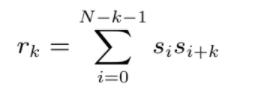

We get the ACF by plotting r_k values with respect to k delays.

### Procedure:

We take different sound segments (a vowel /i/ and consonant /s/ in our case) from original speech signal. We then use a user defined function *ACF(no_of_samples, signal) *to compute the autocorrelation function of a respective sound segment and then plot ACF vs delay for each sound. We then see the ACF for different frame sizes and make observations.

### Code:

**Taking different window sizes**

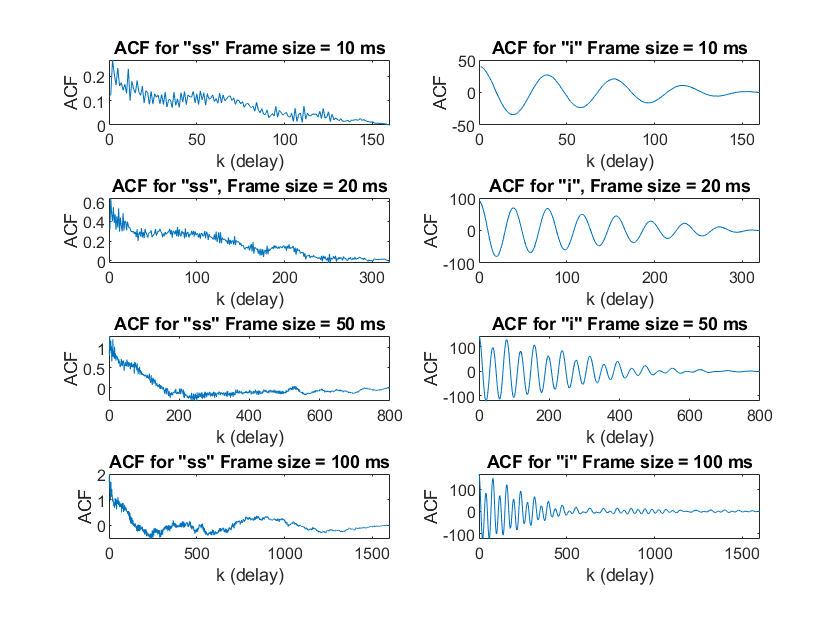

close hidden
ss_sound = sound_sample(int64(0.060*fs):int64((0.060+0.1)*fs));  % fricative
i_sound = sound_sample(int64(1.01*fs):int64((1.01+0.1)*fs));   % vowel

% Frame size = 10 ms
frame_size = 0.010;
N = frame_size*fs; % no. of samples 

subplot(421);
ACF = autocorr(N, ss_sound, 'R');
plot((1:N), ACF);
title('ACF for "ss" Frame size = 10 ms');
xlabel('k (delay)');
ylabel('ACF');

subplot(422);
ACF = autocorr(N, i_sound, 'R');
plot((1:N), ACF);
title('ACF for "i" Frame size = 10 ms');
xlabel('k (delay)');
ylabel('ACF');

% Frame size = 20 ms
frame_size = 0.020;
N = frame_size*fs; % no. of samples 

subplot(423);
ACF = autocorr(N, ss_sound, 'R');
plot((1:N), ACF);
title('ACF for "ss", Frame size = 20 ms');
xlabel('k (delay)');
ylabel('ACF');

subplot(424);
ACF = autocorr(N, i_sound, 'R');
plot((1:N), ACF);
title('ACF for "i", Frame size = 20 ms');
xlabel('k (delay)');
ylabel('ACF');

% Frame size = 50 ms
frame_size = 0.050;
N = frame_size*fs; % no. of samples 

subplot(425);
ACF = autocorr(N, ss_sound, 'R');
plot((1:N), ACF);
title('ACF for "ss" Frame size = 50 ms');
xlabel('k (delay)');
ylabel('ACF');

subplot(426);
ACF = autocorr(N, i_sound, 'R');
plot((1:N), ACF);
title('ACF for "i" Frame size = 50 ms');
xlabel('k (delay)');
ylabel('ACF');

% Frame size = 100 ms
frame_size = 0.100;
N = frame_size*fs; % no. of samples 

subplot(427);
ACF = autocorr(N, ss_sound, 'R');
plot((1:N), ACF);
title('ACF for "ss" Frame size = 100 ms');
xlabel('k (delay)');
ylabel('ACF');

subplot(428);
ACF = autocorr(N, i_sound, 'R');
plot((1:N), ACF);
title('ACF for "i" Frame size = 100 ms');
xlabel('k (delay)');
ylabel('ACF');

**Magnified Plots:**

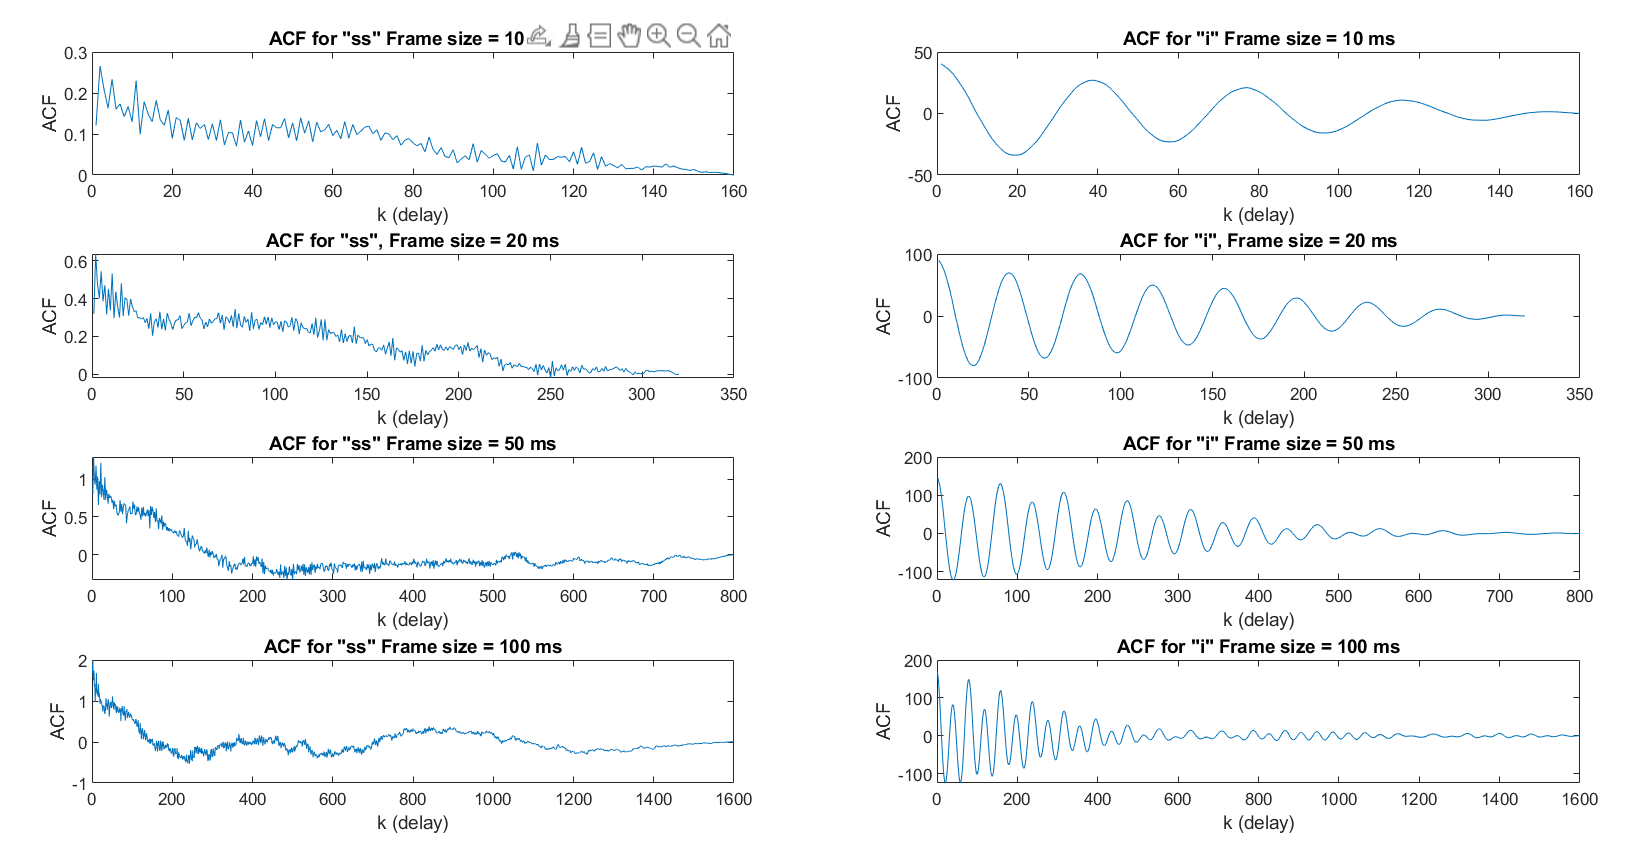

**Observations:**

 We see that as we increase the frame size, the higher delays are not really showing much information (it is getting attenuated). The quasi stationarity assumption weakens as frame size increases hence we should not take very high frame size. Also 10 ms frame size is too short for analysis purpose (we need some more number of cycles) hence i will choose 20 ms frame size as it shows a good representation. 

**Comparing different windows**

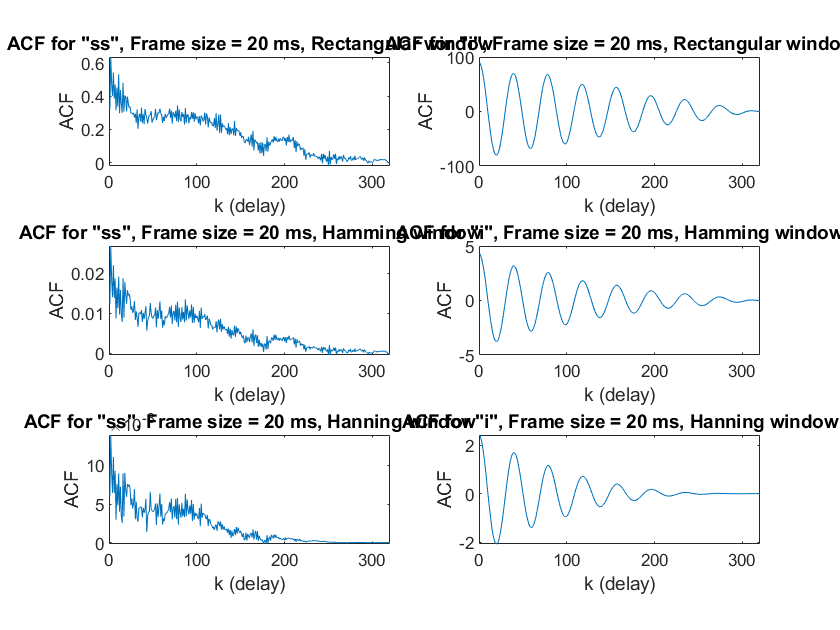

close hidden

% Frame size = 20 ms
frame_size = 0.020;
N = frame_size*fs; % no. of samples 

ACF = autocorr(N, ss_sound, 'R');
subplot(321)
plot((1:N), ACF);
title('ACF for "ss", Frame size = 20 ms, Rectangular window');
xlabel('k (delay)');
ylabel('ACF');

ACF = autocorr(N, i_sound, 'R');
subplot(322)
plot((1:N), ACF);
title('ACF for "i", Frame size = 20 ms, Rectangular window');
xlabel('k (delay)');
ylabel('ACF');

ACF = autocorr(N, ss_sound, 'Hamm');
subplot(323)
plot((1:N), ACF);
title('ACF for "ss", Frame size = 20 ms, Hamming window');
xlabel('k (delay)');
ylabel('ACF');

ACF = autocorr(N, i_sound, 'Hamm');
subplot(324)
plot((1:N), ACF);
title('ACF for "i", Frame size = 20 ms, Hamming window');
xlabel('k (delay)');
ylabel('ACF');

ACF = autocorr(N, ss_sound, 'Hann');
subplot(325)
plot((1:N), ACF);
title('ACF for "ss", Frame size = 20 ms, Hanning window');
xlabel('k (delay)');
ylabel('ACF');

ACF = autocorr(N, i_sound, 'Hann');
subplot(326)
plot((1:N), ACF);
title('ACF for "i", Frame size = 20 ms, Hanning window');
xlabel('k (delay)');
ylabel('ACF');

**Magnified Plots:**

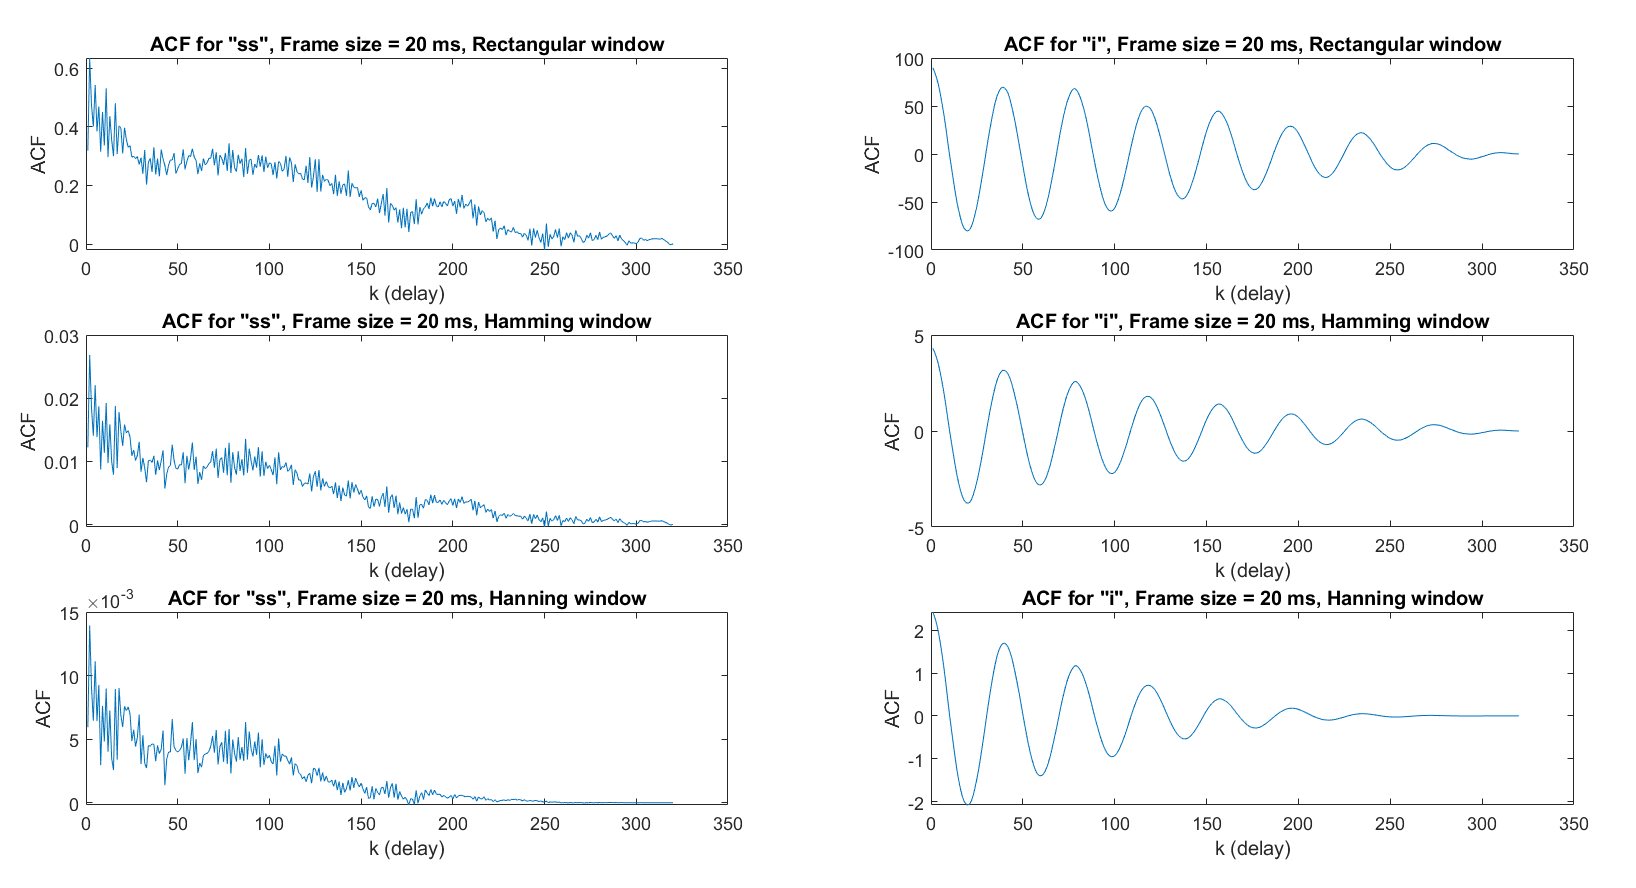

**Observations: **

 We see very small differences in the shape of the waveform but we see that the ACF values have changed drastically when different windows are used. I feel hamming window is a good window we can use as it has a more accurate representation of the ACF (it looks more similar to the case of rectangular window). Hanning window shows attenuation much earlier as compared to hamming windows. We use windows so that the abruptness between frames can be reduced and amongst hamming and hanning, I would prefer to use hamming window.

### Function Definitions

function plot_time_signal(y, fs, title_name)  % PLOT TIME DOMAIN PLOT FOR ANY SIGNAL
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

function plot_freq_spectrum(x, fs, title_name)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    X_mags = 20*log10(abs(fft(x, n)));
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude (dB)');
    title(title_name);
end

% PLOT FOR ANY SIGNAL
function plotting(x, y, title_name, x_label, y_label)
    plot(x,y);
    xlabel(x_label);
    ylabel(y_label);
    title(title_name);
end

% CALCULATING AUTO CORRELATION FUNCTION
function ACF = autocorr(no_of_samples, signal, window)
    if strcmp(window, 'Hamm')
        win = dsp.Window("Hamming"); % Hamming window
        signal = win(signal);
    end
    if strcmp(window, 'Hann')
        win = dsp.Window("Hanning"); % Hanning window
        signal = win(signal);
    end
    if strcmp(window, 'R') % Rectangular window
        signal = signal;
    end
    
    N = no_of_samples;
    ACF = [];
    
    for i = 1:N 
        sum = 0;
        
        for j = 1:N-i
            sum = sum + signal(j)*signal(j+i);
        end
        
        ACF = [ACF sum];
    end
    
end

% CALCULATING SHORT TIME ENERGY FRAME BY FRAME FOR A GIVEN FRAME SIZE AND
% FRAME SHIFT FOR ANY SIGNAL 
function [no_of_frames, E] = calculate_energy(fs, frame_size, frame_shift, signal)
    no_of_frames = length(0:frame_shift:length(signal)/fs-frame_size);
    
    E = [];
    n = 0;
    
    for i = 1:no_of_frames
        % getting segment of speech for a particular frame index
        x = signal((1+round((n*frame_shift)*fs)):(round((n*frame_shift + frame_size)*fs)));
        sum = 0;
        
        for j = 1:length(x)
            sum = sum + x(j)*x(j);
        end
        
        E = [E sum];
        n = n+1;
    end
end

% CALCULATING ZCR FRAME BY FRAME FOR A GIVEN FRAME SIZE AND
% FRAME SHIFT FOR ANY SIGNAL 
function [no_of_frames, zcr] = calculate_zcr(fs, frame_size, frame_shift, signal)
    no_of_frames = length(0:frame_shift:length(signal)/fs-frame_size);
    
    zcr = [];
    n = 0;
    
    for i = 1:no_of_frames
        % getting segment of speech for a particular frame index
        x = signal((1+round((n*frame_shift)*fs)):(round((n*frame_shift + frame_size)*fs)));
        
        count = 0;
        
        for j = 2:length(x)
            if((x(j-1) >=0 && x(j) <0) || (x(j-1) < 0 && x(j) >= 0) )
                count = count + 1; 
            end
        end
        
        zcr = [zcr count];
        n = n+1;
    end
end